240032 ExFinal Q1 2021-22 Problema 2

## Problem 2

Let us consider the domain $\Omega$, meshed by means of two elements (a quadrilateral and a triangle) as follows. Nodes: $(0,0), (2,0), (5,0), (0,1), (2,1)$. Connectivity matrix: $\left(\begin{array}{cccc} 1 & 2 & 5 & 4\\ 5 & 2 & 3 & *\end{array}\right)$.

Using this mesh we are going to consider the finite element method for the following problem


$$\left\{\begin{array}{rcl}
-k_{c}\Delta u\!\!\!\! &=&\!\!\!\!\! f,\quad \text{ on }\Omega,\\
u(x,0)\!\!\!\! &=& \!\!\!\! 3x,\\
u(0,y))\!\!\!\! &=& \!\!\!\!  2y,\\
\frac{\partial u}{\partial y}(x,y) \!\!\!\! &=& \!\!\!\! 2,\quad \text{on the line joining nodes $4$ and $5$},\\
\frac{\partial u}{\partial n}(x,y) \!\!\!\! &=& \!\!\!\! 2,\quad \text{on the line joining nodes $3$ and $5$}.\\

\end{array}\right.$$


where $k_{c} = 12$, $f\equiv 2$ on $\Omega^{1}$, $f\equiv 4$ on $\Omega^{2}$.

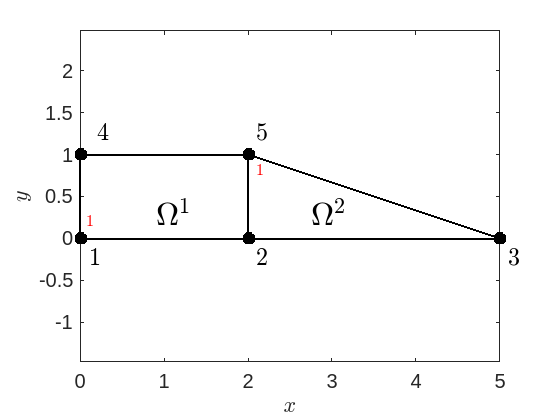

clearvars
close all

%Data
k1=12.0; f1=2;
k2=6.0; f2=4;

nodes = [0.0 ,0.0;
    2.0, 0.0;
    5.0, 0.0;
    0.0, 1.0;
    2.0, 1.0];

elem = [1, 2, 5, 4;
    5, 2, 3, 0];

vertexs = [nodes(1,:);
    nodes(2,:); nodes(5,:); nodes(4,:); nodes(1,:)];
plot(vertexs(:,1), vertexs(:,2),'-ok','MarkerFaceColor','black',...
    'MarkerSize',8,'lineWidth',1.5)
hold on
axis equal
vertexs = [nodes(2,:); nodes(3,:); nodes(5,:)];

plot(vertexs(:,1), vertexs(:,2),'-ok','MarkerFaceColor','black',...
    'MarkerSize',8,'lineWidth',1.5)
plot(nodes(3,1), nodes(3,2),'-ok','MarkerFaceColor','black',...
    'MarkerSize', 8)

text(0.9,0.25,'$\Omega^{1}$','interpreter','LaTeX','FontSize',24)
text(2.75,0.25,'$\Omega^{2}$','interpreter','LaTeX','FontSize',24)

text(0.1,-0.25,'$1$','Interpreter','LaTeX','FontSize',18)
text(2.1,-0.25,'$2$','Interpreter','LaTeX','FontSize',18)
text(5.1,-0.25,'$3$','Interpreter','LaTeX','FontSize',18)
text(2.1,1.25,'$5$','Interpreter','LaTeX','FontSize',18)
text(0.2,1.25,'$4$','Interpreter','LaTeX','FontSize',18)

text(0.07,0.2,'$1$','Interpreter','LaTeX','FontSize',12,'Color','red')
text(2.1,0.8,'$1$','Interpreter','LaTeX','FontSize',12,'Color','red')
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$y$','Interpreter','latex','FontSize',14)
hold off


dudy=2.0; %on the line joining nodes 4 and 5
q1_3=k1*dudy; 

%Rectangle: elem 1 
vertexsR=nodes(elem(1,:),:);
a = norm(vertexsR(2,:)-vertexsR(1,:));
b = norm(vertexsR(4,:)-vertexsR(1,:));

Psi1=@(x,y) (x-vertexsR(2,1))*(y-vertexsR(3,2))/a/b;
Psi2=@(x,y) -(x-vertexsR(1,1))*(y-vertexsR(3,2))/a/b;
Psi3=@(x,y) (x-vertexsR(1,1))*(y-vertexsR(1,2))/a/b;
Psi4=@(x,y) -(x-vertexsR(2,1))*(y-vertexsR(1,2))/a/b;

%Stifness Matrix
A=[2,-2,-1, 1;
  -2, 2, 1,-1;
  -1, 1, 2,-2;
   1,-1,-2, 2];

B=[2, 1,-1,-2;
   1, 2,-2,-1;
  -1,-2, 2, 1;
  -2,-1, 1, 2];


K=b*k1*A/a + a*k1*B/b;
K=K/6;

F=0.25*f1*a*b*[1;1;1;1];

Q1_33=q1_3*a/2; 

%Triangle: elem 2
vertexsT=nodes(elem(2,1:3),:);
a=norm(vertexsT(2,:)-vertexsT(1,:));
b=norm(vertexsT(3,:)-vertexsT(2,:));

b2=b*b;
a2=a*a;

A=[b2,   -b2,    0; 
  -b2, a2+b2,  -a2;
    0,   -a2,   a2];

L=0.5*k2*A/a/b;

G=f2*a*b*[1;1;1]/6;

%Natural B.C;
Q2_13=0.0; %q2_3=0 on the line joining nodes 3 and 5
Q5=Q1_33+Q2_13;

%Essential B.C.
U1=0.0;
U2=3*nodes(2,1);
U3=3*nodes(3,1);
U4=2*nodes(4,2);
um=[U1;U2;U3;U4];
k=[0.0,K(3,2)+L(1,2),0.0,K(3,4),K(3,3)+L(1,1)];
U5=(F(3)+G(1)+Q5-k(1:4)*um)/k(5); 
    

%Solutions
clc
fprintf('====================================================\n')

fprintf('                       PROB.2                       \n')

                       PROB.2                       


fprintf('====================================================\n')

fprintf('********************** PART A **********************\n')

********************** PART A **********************


fprintf('Psi1(2;0.5,0.5) = %.5e\n',Psi2(0.5,0.5))

Psi1(2;0.5,0.5) = 1.25000e-01


fprintf('********************** PART B **********************\n')

********************** PART B **********************


fprintf('K(5,2) = %.5e\n',K(3,2)+L(1,2));

K(5,2) = -1.60000e+01


fprintf('********************** PART C **********************\n')

********************** PART C **********************


fprintf('F(5) = %.5e\n',F(3)+G(1));

F(5) = 3.00000e+00


fprintf('********************** PART D **********************\n')

********************** PART D **********************


fprintf('Q1_33 = %.5e\n',Q1_33);

Q1_33 = 2.40000e+01


fprintf('********************** PART E **********************\n')

********************** PART E **********************


fprintf('U(5) = %.5e\n',U5);

U(5) = 6.26316e+00


fprintf('****************************************************\n')

****************************************************
